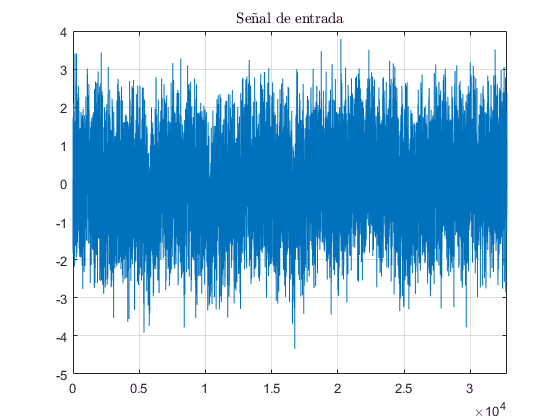

clear
data = load('h06g1.dat');
n = length(data);
figure();
plot(data);
grid on;
title('Se\~{n}al de entrada', 'interpreter', 'latex');
xlim([0 n]);

pmax = 9;

Se calcula la media y la varianza de los datos y luego se calcula la autocorrelacion mediante el estimador no polarizado:


$$R_{np}(k)=\frac{1}{n-k} \cdot \sum_{i=1}^{n-k}X_i\cdot X_{i+k} $$


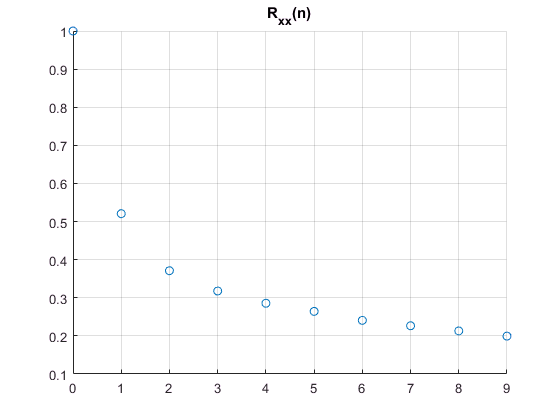

mu = mean(data);
variance = var(data);
Rxx = zeros(pmax + 1, 1);
for p = 1:(pmax + 1)
    k = p - 1;
    Rxx(p) = 1 / (n - k) * sum(data(1:n-k) .* data(p:n));
end
scatter(0:pmax, Rxx)
title('R_{xx}(n)')
grid

Ahora se buscan, para cada **p=1,...,9**, los parametros de un modelo AR(p) que ajuste a los datos provistos. Para ello se utiliza la **ecuacion de Yule-Walker:**

 
$$\vec{\Phi_p} = R^{-1}_p \cdot \vec{r_{xx}}$$


% R: matriz que contiene las 9 matrices para calcular cada Phi
% R(p,1:p,1:p) es la matriz que permite calcular Phi_p
R = zeros(pmax, pmax, pmax);
% Phi: matriz que contiene los 9 vectores con los coeficientes de
%      correlacion parcial. Phi(p,1:p) contiene Phi_p
Phi = zeros(pmax);
for p=1:pmax
    % Armamos la matriz R
    for i=1:p
        for j=1:p
            R(p,i,j) = Rxx(abs(i-j)+1) / Rxx(1);
        end
    end
    % Armamos vector rxx con rxx(1) a rxx(p)
    fprintf('Yule-Walker para p = %i', p);
    rxx = Rxx(2:p+1) ./ Rxx(1);
    auxR = squeeze(R(p,1:p,1:p));   % squeeze para que pase de "1xpxp" a "pxp"
    fprintf('R%i = ', p);
    disp(auxR);
    Phi(p, 1:p) = auxR \ rxx;
    fprintf('Phi%i = ', p);
    disp(squeeze(Phi(p,1:p)));
    fprintf(' ')
end

Yule-Walker para p = 1

R1 = 

     1



Phi1 = 

    0.5206



Yule-Walker para p = 2

R2 = 

    1.0000    0.5206
    0.5206    1.0000



Phi2 = 

    0.4493    0.1371



Yule-Walker para p = 3

R3 = 

    1.0000    0.5206    0.3710
    0.5206    1.0000    0.5206
    0.3710    0.5206    1.0000



Phi3 = 

    0.4340    0.0871    0.1113



Yule-Walker para p = 4

R4 = 

    1.0000    0.5206    0.3710    0.3177
    0.5206    1.0000    0.5206    0.3710
    0.3710    0.5206    1.0000    0.5206
    0.3177    0.3710    0.5206    1.0000



Phi4 = 

    0.4249    0.0800    0.0761    0.0813



Yule-Walker para p = 5

R5 = 

    1.0000    0.5206    0.3710    0.3177    0.2856
    0.5206    1.0000    0.5206    0.3710    0.3177
    0.3710    0.5206    1.0000    0.5206    0.3710
    0.3177    0.3710    0.5206    1.0000    0.5206
    0.2856    0.3177    0.3710    0.5206    1.0000



Phi5 = 

    0.4195    0.0749    0.0707    0.0529    0.0669



Yule-Walker para p = 6

R6 = 

    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642
    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856
    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177
    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710
    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206
    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000



Phi6 = 

    0.4165    0.0725    0.0675    0.0495    0.0479    0.0452



Yule-Walker para p = 7

R7 = 

    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642    0.2407
    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642
    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856
    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177
    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710
    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206
    0.2407    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000



Phi7 = 

    0.4145    0.0704    0.0653    0.0465    0.0447    0.0268    0.0442



Yule-Walker para p = 8

R8 = 

    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642    0.2407    0.2265
    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642    0.2407
    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642
    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856
    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177
    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710
    0.2407    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206
    0.2265    0.2407    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000



Phi8 = 

    0.4129    0.0695    0.0638    0.0449    0.0424    0.0243    0.0295    0.0354



Yule-Walker para p = 9

R9 = 

    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642    0.2407    0.2265    0.2131
    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642    0.2407    0.2265
    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642    0.2407
    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856    0.2642
    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177    0.2856
    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710    0.3177
    0.2407    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206    0.3710
    0.2265    0.2407    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000    0.5206
    0.2131    0.2265    0.2407    0.2642    0.2856    0.3177    0.3710    0.5206    1.0000



Phi9 = 

    0.4120    0.0686    0.0631    0.0437    0.0412    0.0225    0.0276    0.0239    0.0276



No se observa que se anulen ninguno de los $\phi_{k,k}$, por lo cual no se puede afirmar que alguno de los modelos se haya ajustado correctamente.

Para cada modelo AR(p) se plantea el siguiente modelo de estados para el filtro de Kalman:


$$\textbf{x}_{k+1}=\phi_p \cdot \textbf{x}_{k}+\textbf{w}_k$$



$$z_k=\textbf{H}_k\cdot\textbf{x}_k+v_k$$


Donde:


$$\textbf{x}_k=\pmatrix{x(k) \cr x(k-1) \cr \vdots \cr x(k-p+1)  }$$



$$\phi_p = \pmatrix{\phi_{p,1} & \phi_{p,2} & ... & \phi_{p,p-1} & \phi_{p,p} \cr 
1 & 0 & ... & 0 & 0 \cr
0 & 1 & ... & 0 & 0 \cr
\vdots &  & \ddots & \vdots & \vdots \cr
0 & 0 & ... & 1 & 0 }  \, \epsilon \, {R}^{pxp}$$



$$\textbf{w}_k = \pmatrix{ w_k \cr 0 \cr 0 \cr \vdots \cr 0 }  \, \epsilon \, \mathbb{R}^{px1}$$



$$\textbf{H}_k = \pmatrix{1 & 0 & \dots & 0} \, \epsilon \, \mathbb{R}^{1xp}$$


$v_k$: ruido blanco gaussiano de varianza $\sigma_v^2$

vars_len = 15;
vars = logspace(-2,1,vars_len);
var_to_plot = 13;

nmax = n;
nplot = 100;

mse_input = zeros(pmax,1);
mse_output = zeros(pmax,1);
improvements = [];


for varV = vars
    Z = data(1:nmax) + wgn(nmax, 1, 10*log10(varV));
    
    for p=1:pmax
        
        Phip = zeros(p);
        Phip(1,:) = Phi(p,1:p);
        Phip(2:end,:) = [ eye(p-1) zeros(p-1,1) ];
    
        Hk = zeros(1,p);
        Hk(1) = 1;
        
        varN = variance * (1 - dot(Phi(p,1:p), rxx(1:p)));
        
        Qk = zeros(p);
        Qk(1,1) = varN;
        Rk = varV;
        
        Xminus = [ mu ; zeros(p-1,1) ];
        % x's covariance matrix was used for Yule-Walker
        Pminus = squeeze(R(p,1:p,1:p));
        % Run Filter
        output = zeros(nmax,1);
        input = zeros(nmax,1);
        for k=1:nmax

           Se obtiene la ganancia de Kalman:

           
$$\textbf{K}_k=\textbf{P}_k^-\textbf{H}_k^T(\textbf{H}_k\textbf{P}_k^-\textbf{H}_k^T+\textbf{R}_k)^{-1}$$


            Kk = Pminus*Hk'*inv(Hk*Pminus*Hk'+Rk);

           Se actualizan las estimaciones con las mediciones Z(k). Esta es la salida del filtro:

            
$$\hat{\textbf{x}}_k = \hat{\textbf{x}}_k^-+\textbf{K}_k(\textbf{z}_k-\textbf{H}_k\hat{\textbf{x}}_k^-)$$


            Xk = Xminus + Kk*(Z(k) - Hk*Xminus);

            Se obtiene la covarianza del error para la nueva estimacion:

            
$$\textbf{P}_k=(\textbf{I}-\textbf{K}_k\textbf{H}_k)\textbf{P}_k^-$$


            Pk = (eye(p)-Kk*Hk)*Pminus;

            Se proyecta hacia adelante. Esta es la salida si se utiliza como predictor:

            
$$\hat{\textbf{x}}^-_{k+1} = \phi_k\hat{\textbf{x}}_k$$


            
$$\textbf{P}_{k+1}^-=\phi_k\textbf{P}_k\phi_k^T+\textbf{Q}_k$$


            Xminus = Phip*Xk;
            Pminus = Phip*Pk*Phip' + Qk;
            input(k) = Z(k);
            output(k) = Xk(1);
        end
        

Se calcula el error cuadratico de la entrada con ruido, y la salida filtrada, ambos con respecto a los datos originales.

        err_input = (data(1:nmax) - input).^2;
        err_output = (data(1:nmax) - output).^2;
        mse_input(p) = mean(err_input);
        mse_output(p) = mean(err_output);
        

Se elige una de las varianzas para graficar de forma representativa.    

        if (varV == vars(var_to_plot) && (p == 2 || p == 9)) 
            figure()
            plot([data((nmax-nplot):nmax) input((nmax-nplot):end) output((nmax-nplot):end)]);
            legend({'Data', 'Data + ruido', 'Output filtrado'});
            title(sprintf('Salida del filtro para $$\\sigma_v^2$$ = %.2f y p = %i', varV, p), 'interpreter', 'latex');
            xlim([0 nplot]);
            grid on;
            
            figure()
            plot([err_input err_output]);
            legend({'Error cuadrático sin filtrado', 'Error cuadrático con filtrado'});
          %  title(sprintf("Comparaci\\'on de errores cuadr\\'aticos para $$\\sigma_v^2$$ = %.2f y p = %i", varV, p), 'interpreter', 'latex');
            xlim([0 nmax]);
            grid on;
            
        end
    end

Si se observan los datos originales, la entrada ruidosa, y la salida filtrada en el tiempo, se puede apreciar que el filtro esta actuando correctamente, dado que la salida filtrada se asemeja mas a los valores originales. Esto se condice con lo observado en el grafico del error cuadratico, el cual presenta una mejora considerable.

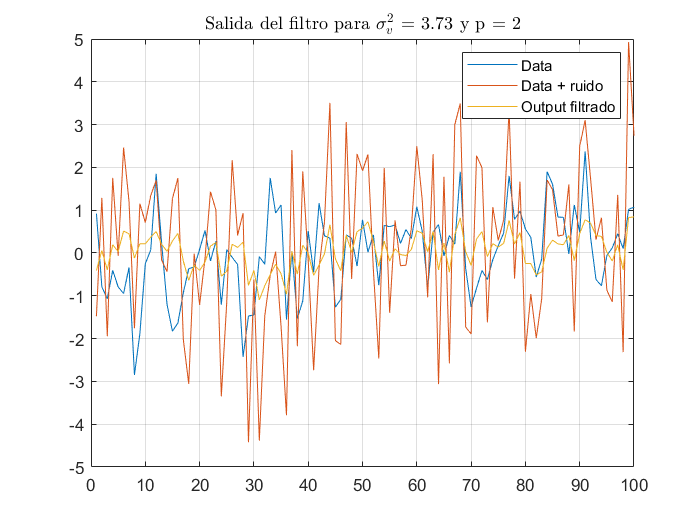

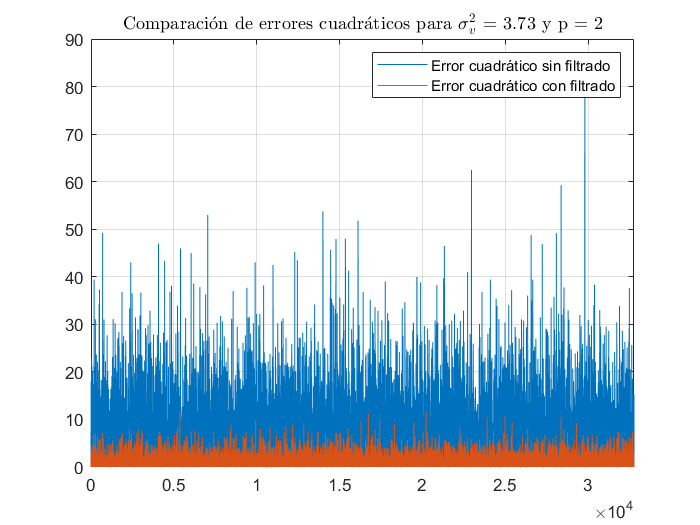

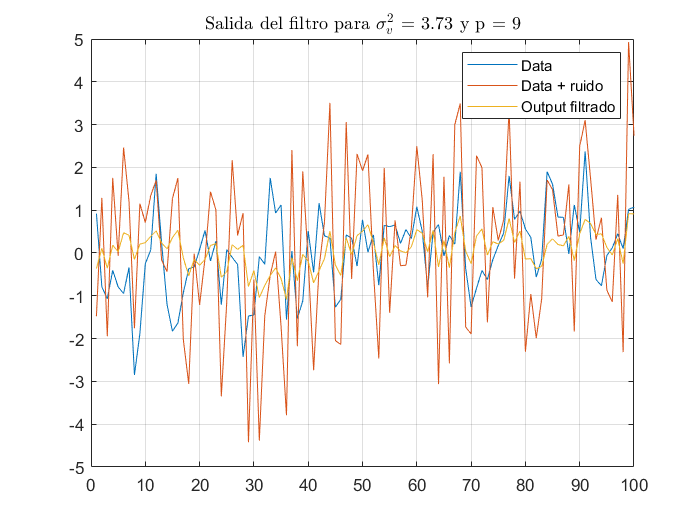

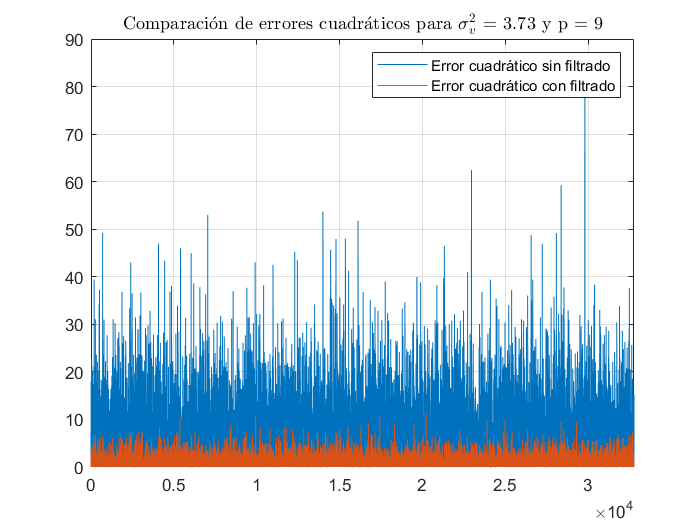

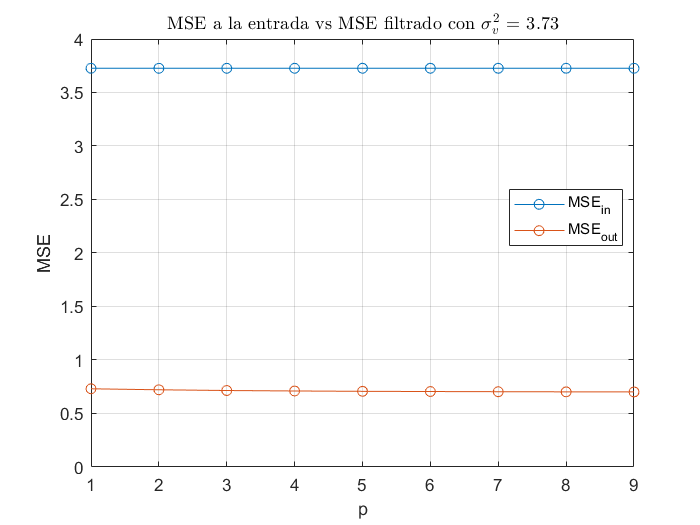

    if (varV == vars(var_to_plot))
       figure()
       plot([mse_input mse_output], '-o');
       title(sprintf('MSE a la entrada vs MSE filtrado con $$\\sigma_v^2$$ = %.2f', varV), 'interpreter', 'latex');
       grid on;
       xlabel('p');
       ylabel('MSE');
       legend({'MSE_{in}', 'MSE_{out}'}, 'Location', 'best');
       ylim([0 4])
    end
    
    % Se guarda la informacion de en cuantas veces el filtro mejoro el MSE, con respecto al MSE de la señal con ruido.
    improvements = [improvements mean((mse_input - mse_output) ./ mse_input)];
end  

Respecto de la variacion del orden del modelo AR, se observa en todos los ordenes una mejora considerable del MSE en contraste al de la entrada. Sin embargo, no es tan apreciable la mejora conforme aumenta el orden del modelo. Esto puede deberse al hecho de que para ningun orden se cumple la condicion de $\phi_{k,k} \approx 0$, para $k>p$, es decir, no se ajustan bien.

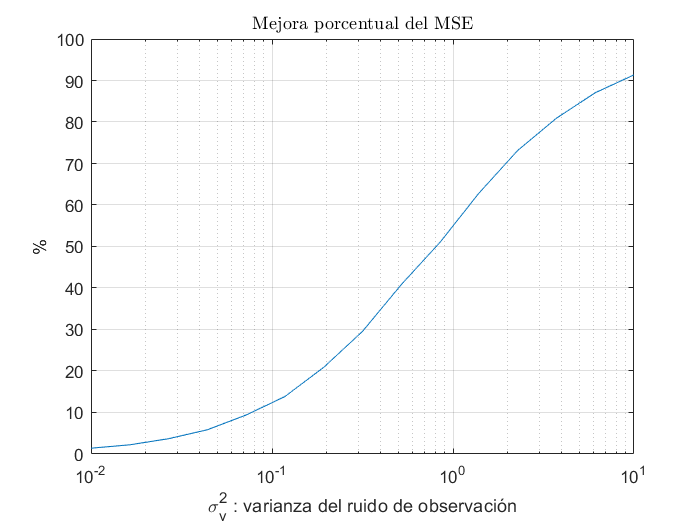

figure()
semilogx(vars, improvements .* 100)
grid on
title('Mejora porcentual del MSE', 'interpreter', 'latex');
xlabel('\sigma_v^2 : varianza del ruido de observación')
ylabel('%')

Debido a que cuando la varianza del ruido es muy baja, no hay mucho margen para la mejora con el filtro, la mejora porcentual del MSE no es amplia. Sin embargo, al aumentar la misma, la influencia del filtro de Kalman se hace mucho mas notoria, llegando a mejoras del 90%.